# Fourier Analysis for Spectral Estimation

addpath('tutorial_functions')

## Introduction

The aim for this tutorial is to produce a function that can be used to estimate frequency content of a signal.

## Basic definitions (Continuous signals)

Consider a continuous periodic signal that is a function of time $t$ and space $x$, say $p(x,t)$.  Any **periodic** signal can be decomposed in the following ways, all of which are equivalent:

- 
$$p\left(x,t\right)=\frac{A_0 \left(x\right)}{2}+\;\sum_{m=1}^{\infty } A_m \left(x\right)\cos \left(m\omega \;t\right)+B_m \left(x\right)\;\sin \left(m\omega t\right)\;\;\;\;\;\;\;\;\;\;\left(\textrm{Eq}\ldotp \;1\right)$$


- 
$$p\left(x,t\right)=\frac{C_0 \left(x\right)}{2}+\;\sum_{m=1}^{\infty } C_m \left(x\right)\cos \left(m\omega \;t-\phi_m \left(x\right)\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{Eq}\ldotp \;2\right)$$


- 
$$p\left(x,t\right)=\Re \left\lbrace \sum_{m=-\infty \;}^{\infty } {\hat{D} }_m \left(x\right)\exp \left(i\;m\omega t\right)\right\rbrace \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{Eq}\ldotp \;3\right)$$


The **aim is to be able to estimate**:

- for case (1) $A_m(x)$ and $B_m(x)$, which are real Fourier coefficients.

- for case (2) $C_m(x)$ and $\phi_m(x)$,  which is a real Fourier coefficient and a real phase. 

- for case (3) ${\hat{D} }_m \left(x\right)$, which is a complex quantity with an amplitude and a phase, i.e., ${\hat{D} }_m \left(x\right)=\frac{1}{2}C_m \left(x\right)\;\exp \left(-i\;\phi_m \left(x\right)\right)$. 

For **continuous** signals, with period $T = 2\pi/\omega$,  the coefficients can be estimated using: 

- 
$$A_m =\frac{2}{T}\;\int_0^T p\left(x,t\right)\;\cos \left(m\omega t\right)\;\textrm{dt},{\;\;\;B}_m =\frac{2}{T}\;\int_0^T p\left(x,t\right)\;\sin \left(m\omega t\right)\;\textrm{dt},\;$$


- 
$$C_m =\sqrt{A_m^2 +B_m^2 },\;{\;\;\;\;\;\;\phi }_m =\textrm{arctan2}\left(B_m ,A_m \right)$$
 

- 
$${\hat{D} }_m =\frac{1}{T}\;\int_0^T p\left(x,t\right)\;\exp \left(-i\;m\omega t\right)\;\textrm{dt}\ldotp \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{Eq}\ldotp 4\right)$$


## Basic definitions (Discrete signals)

For a **discrete** signal with sequence $\left\lbrace p_n \right\rbrace =p_0 ,{\;p}_1 ,{\;p}_2 ,\ldotp \ldotp \ldotp ,p_{N-1} \;,$the equivalent definition of the Fourier series  is given by the **inverse** **Discrete Fourier Transform**:

- 
$${\;p}_n =\frac{1}{N}\sum_{k\;=\;0}^{N-1} P_k \;\exp \left(i\;\frac{2\pi \;}{N}k\;n\right),\;\;\;\;n\in \left\lbrack 0,N-1\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{Eq}\ldotp 5\right)$$


The coefficients $P_k$ are defined through the **Discrete Fourier Transform**: 

- 
$$P_{k\;} =\sum_{n\;=\;0}^{N-1} p_n \;\exp \left(-i\;\frac{2\pi \;}{N}k\;n\right)\;,\;\;\;\;\;k\in \left\lbrack 0,N-1\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\textrm{Eq}\ldotp 6\right)$$


## A basic example

Let's consider the most basic example of a periodic signal, which is a sinusoidal wave with frequency$f$ and amplitude$A$ such that:


$$p\left(x,t\right)=A\;\sin \left(2\;\pi \;f\;t\right)\ldotp$$


First, define and plot the signal: 

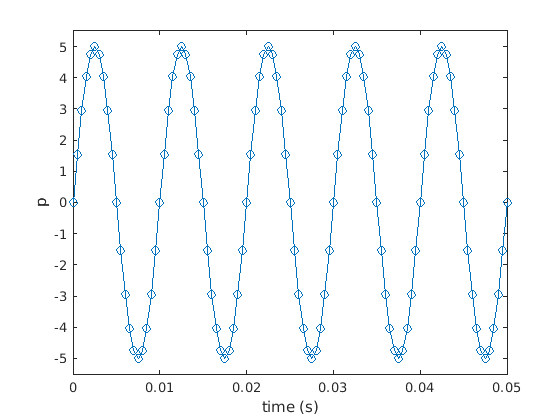

% Generate time vector:
fs = 2000;          % (Hz) Sampling frequency
Ts = 1/fs;           % (s) Sampling period
t = 0:Ts:(10-Ts);    % (s) time vector up to 10 seconds
% Define Amplitude and frequency:
A = 5;
f = 100; % (Hz)
% Basic signal:
p = A*sin(2*pi*f*t);
% Plot
figure
plot(t,p,'-o')
axis([0 0.05 -1.1*A 1.1*A])
xlabel('time (s)')
ylabel('p')

$p(x,t)$ has been discretized into the sequence $\left\lbrace p_n \right\rbrace =p_0 ,{\;p}_1 ,{\;p}_2 ,\ldotp \ldotp \ldotp ,p_{N-1}$. If we want to recover the amplitude $A$ , and the frequency $f$ we first need to compute the coefficients $P_k$ as given in Eq. (6). This is implemented in MATLAB through the command `fft. `

P = fft(p);

By comparing Eq. (3) to Eq. (5) we find that the discrete analogous of ${\hat{D} }_m$ is $P_k/N$.

N = length(p);
P_N = P/N;

Next, since our signal is being sampled at a frequency $f_s$, the frequency bin corresponding to each $P_k$ is given by $f_k \;\;=k\;f_s /N$.  Lets proceed to plot $f$ vs $|P|/N$. 

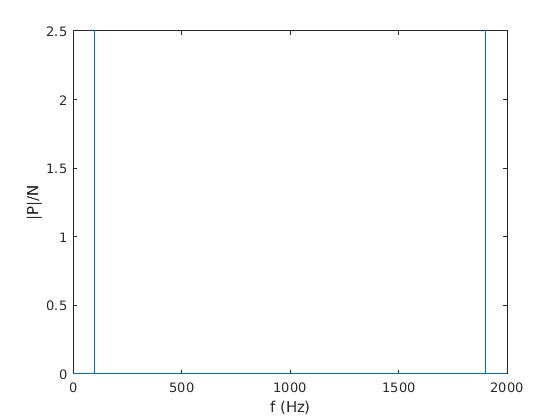

freqs = fs/N*(0:N-1);
% Plot
figure
plot(freqs,abs((P_N)))
xlabel('f (Hz)')
ylabel('|P|/N')

Due to the Nyquist theorem the largest possible resolved frequency is $f_s/2$. That means that all the frequencies $f_k \;\;$with $k > N/2$ will be an alias to a lower frequency component.  By comparing Eq. (3) and Eq. (5) we observe that the frequencies $f_k \;\;$with $k > N/2$ correspond to the negative counterparts of those with $f_k \;\;$with $k < N/2$. Therefore we can shift the entire spectrum accordingly:

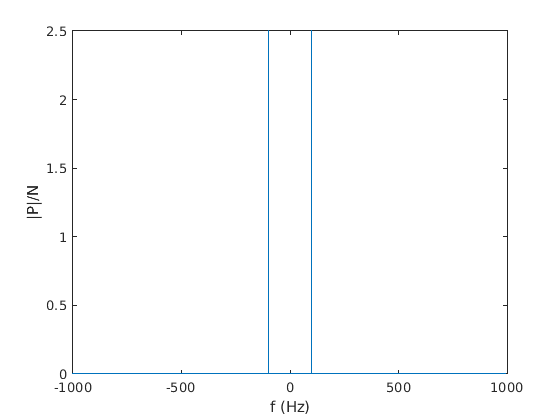

freqs = fs/N*(-N/2:N/2-1);
% Plot
figure
plot(freqs,abs(fftshift(P_N)))
xlabel('f (Hz)')
ylabel('|P|/N')

Finally since our input sequence $\left\lbrace p_n \right\rbrace$ is real the negative side of the spectrum is the complex conjugate of positive side, i.e., $P_{-k} = P_k^*$. This means that if we are only interested in amplitude estimates, we can discard half of the signal and multiply the other half by 2,  noting that the only indices that do not have a complex conjugate are those at $k = 0$ and $k = N/2$ (if $N$ is even) which correspond to the zero frequency and Nyquist frequency. 

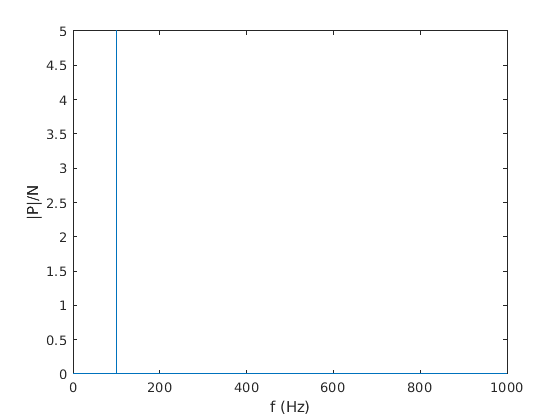

P_N = P_N(1:N/2+1);
P_N(2:end-1) = 2*P_N(2:end-1);
freqs = fs/N*(0:N/2);
% Plot
figure
plot(freqs,abs(P_N))
xlabel('f (Hz)')
ylabel('|P|/N')

Notice from this plot, also called a periodogram, we can easily read that our signal has a single peak with amplitude $A = 5$ at a frequency $f = 100$ Hz. which is what we originally wanted. 

## Further notes

The previous analysis showcases the basics of the fft. In practice, however, this simple techniques may not be enough. Some more advanced techniques may be required for an accurate  esitmation of the amplitude. Some of them include:

- Zero padding - used to increase the frequency resolution.  (If there is no frequency bin ( $f_k$ ) corresponding to the frequency of the signal ($f$), the amplitude estimate may be wrong, then zero padding can be used)

- Windowing - used to crop or smooth signals.  (When a signal is sampled, the end of the signal may not correspond to the beginning of the next cycle, a proper window can be used to make this transition less sharp and reduce spectral leakage).

- Welch method - is the method of averaged periodograms. (When a signal is windowed, the window may influence the amplitude estimates, the Welch method helps reduce the variance and reduce the influence of the window)

- Cross power spectral density - performs cross correlation with a reference signal. (Useful when the phase of the signal is also important, it performs better than simple FFT when there are high noise levels) 

We have implemented these techniques in a simple function called `fn_spectral_est,` which we will show in the next examples. The function first applies zero padding, then uses a Hanning window. It can do this using the Welch method and CPSD with a reference signal. 

## Example 2: Signal with multiple frequencies

Here we will consider a signal with multiple frequencies, and again the task will be to estimate the amplitude and frequency content.

Begin by defining and plotting the signal:

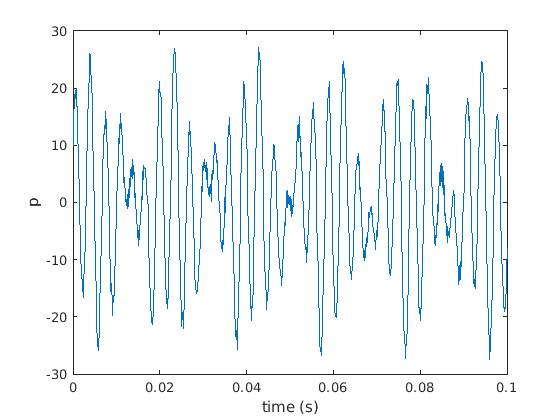

% Generate time vector:
fs = 10000;          % (Hz) Sampling frequency
Ts = 1/fs;           % (s) Sampling period
t = 0:Ts:(10-Ts);    % (s) time vector up to 10 seconds
% Signal:
p = 5*sin(2*pi*100*t) + 10*cos(2*pi*255*t) + 12.5*sin(2*pi*310*t) + randn(size(t));
% Plot
figure
plot(t,p)
xlim([0 0.1])
xlabel('time (s)')
ylabel('p')

Next using the function `fn_spectral_est`, estimate the amplitude and frequency content.

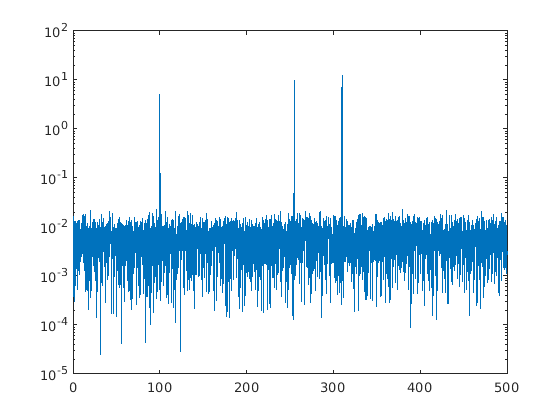

[f,P] = fn_spectral_est(t,p,[],'direct');
% Plot
figure
semilogy(f,abs(P))
xlim([0 500])

Now find the peaks and the frequencies of those peaks:

[Amps,locs] = findpeaks(abs(P),"MinPeakHeight",1);
freqs = f(locs).';
[Amps freqs]

ans =           4.99457606782623          100.002288818359
          9.99347682578153          255.002975463867
          12.4935806040211          310.001373291016


In this case zero padding was used to improve the frequency estimates. 

## Example 3: Signal and reference signal

Here we perform cross correlation to know the amplitude and phase of a signal. 

## Example 4: Frequency sweep

In this case we will consider a signal whose frequency is changing linearly with time, $\omega = 2\pi t$

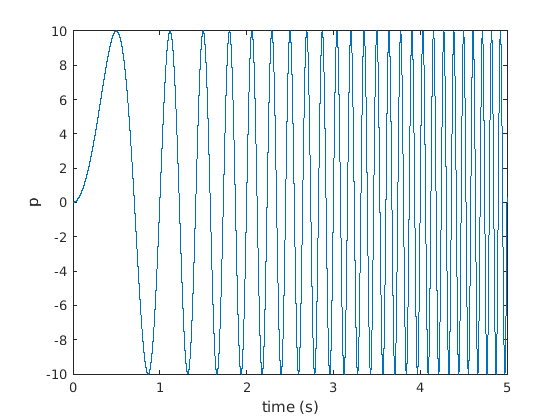

% Generate time vector:
fs = 10000;          % (Hz) Sampling frequency
Ts = 1/fs;           % (s) Sampling period
t = 0:Ts:(10-Ts);    % (s) time vector up to 10 seconds
% Angular frequency:
f = t;
p = 10*sin(2*pi*f.*t);
% Plot
figure
plot(t,p)
xlim([0 5])
xlabel('time (s)')
ylabel('p')

Now

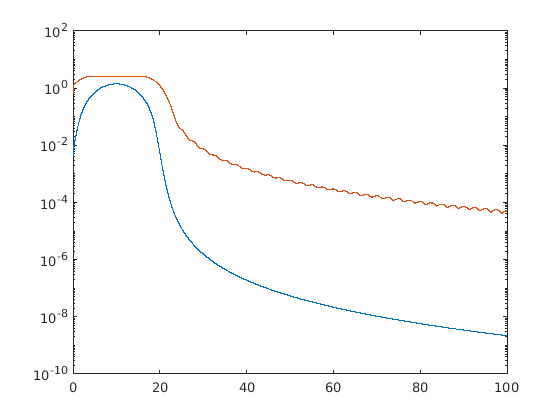

[fd,Pd] = fn_spectral_est(t,p,[],'direct');
Opts.M = 50;
[fw,Pw] = fn_spectral_est(t,p,[],'welch',Opts);
% Plot
figure
semilogy(fd,abs(Pd))
hold on
semilogy(fw,abs(Pw))
xlim([0 100])